## Introduction

In this script, i try to add the potenetial to observe the property

Also the change the history part is changed into a more easy form. 

## Data Importing

import parameters

m=1;%just for test
psi=10;%psi=0---> no potential
zeta=200;
H=0.7;
kB=1;
T=1;

import Time interval

delta=0.01;

import Total Time

Tmax=10;

import Total_experiment_number

Total_experiment_number=20;

## Main loop

initialization

imax=Tmax/delta;
v=zeros(Total_experiment_number,imax+1);
x=zeros(Total_experiment_number,imax+1);
a=zeros(Total_experiment_number,imax+1);

loop

for n=1:Total_experiment_number
    v(n,1)=normrnd(0,(kB*T/m)*0.5);%should be random;
    x(n,1)=0;%no need to be random
    a(n,1)=0;%no need to be random
    BH=wfbm(H,imax+1);
    for i=1:imax
        KH=i:-1:1;
        x(n,i+1)=x(n,i)+v(n,i)*delta;
        v(n,i+1)=v(n,i)+a(n,i)*delta;
        a(n,i+1)=-(zeta/m)*2*H*(2*H-1)*delta^(2*H-2)*((KH.^(2*H-2))*v(n,1:i)')*delta-psi*x(n,i)+(2*zeta*kB*T)^0.5*(BH(i+1)-BH(i))/delta;%ODE
    end

monitoring the progress rate

    progress_rate=n/Total_experiment_number*100;
    if progress_rate==floor(progress_rate)
        disp(['progress rate  ',num2str(progress_rate),' %'])
    end
end

progress rate  5 %
progress rate  10 %
progress rate  15 %
progress rate  20 %
progress rate  25 %
progress rate  30 %
progress rate  35 %
progress rate  40 %
progress rate  45 %
progress rate  50 %
progress rate  60 %
progress rate  65 %
progress rate  70 %
progress rate  75 %
progress rate  80 %
progress rate  85 %
progress rate  90 %
progress rate  95 %
progress rate  100 %


## Output and plotting

averageX=zeros(imax+1,1);
RMSX=zeros(imax+1,1);
for i=1:imax+1
    averageX(i,1)=sum(x(:,i))/Total_experiment_number;
    RMSX(i,1)=sum(x(:,i).^2)/Total_experiment_number-averageX(i,1)^2;
end

plotting

figure_RMS=plot(RMSX,"LineWidth",2)

figure_RMS =   Line - 属性:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×1001 double]
              YData: [1×1001 double]
              ZData: [1×0 double]

  显示 所有属性


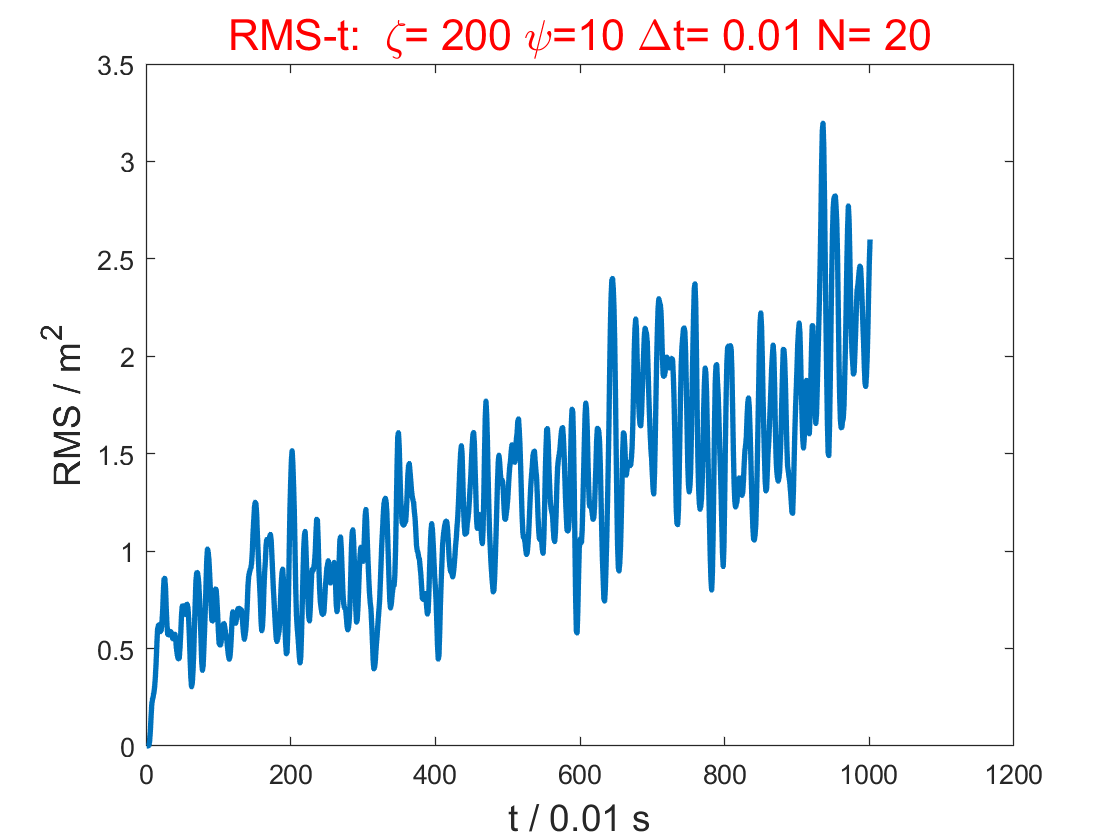

xlabel(['t / ',num2str(delta),' s'],'FontSize',14)
ylabel('RMS / m^2','FontSize',14)
title(['RMS-t: ',' \zeta= ',num2str(zeta),' \psi=', ...
    num2str(psi),' \Deltat= ',num2str(delta),' N= ', ...
    num2str(Total_experiment_number)],'Color','r','FontSize',16)
saveas(figure_RMS,['v3image\RMS','.zeta=',num2str(zeta),'.psi=',num2str(psi),'N=',num2str(Total_experiment_number),'.jpg'])

figure_average=plot(averageX,"LineWidth",2)

figure_average =   Line - 属性:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×1001 double]
              YData: [1×1001 double]
              ZData: [1×0 double]

  显示 所有属性


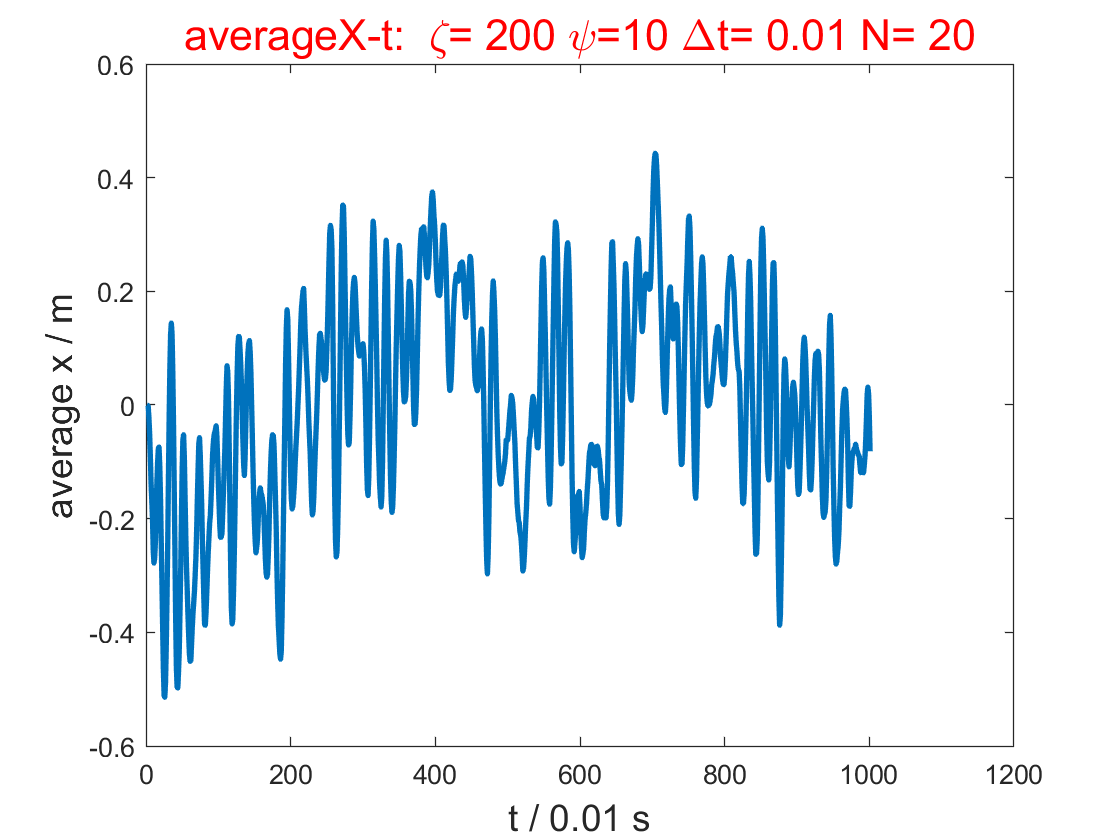

xlabel(['t / ',num2str(delta),' s'],'FontSize',14)
ylabel('average x / m','FontSize',14)
title(['averageX-t: ',' \zeta= ',num2str(zeta), ...
    ' \psi=',num2str(psi),' \Deltat= ',num2str(delta), ...
    ' N= ',num2str(Total_experiment_number)],'Color','r','FontSize',16)
saveas(figure_average,['v3image\average','.zeta=',num2str(zeta),'.psi=',num2str(psi),'N=',num2str(Total_experiment_number),'.jpg'])